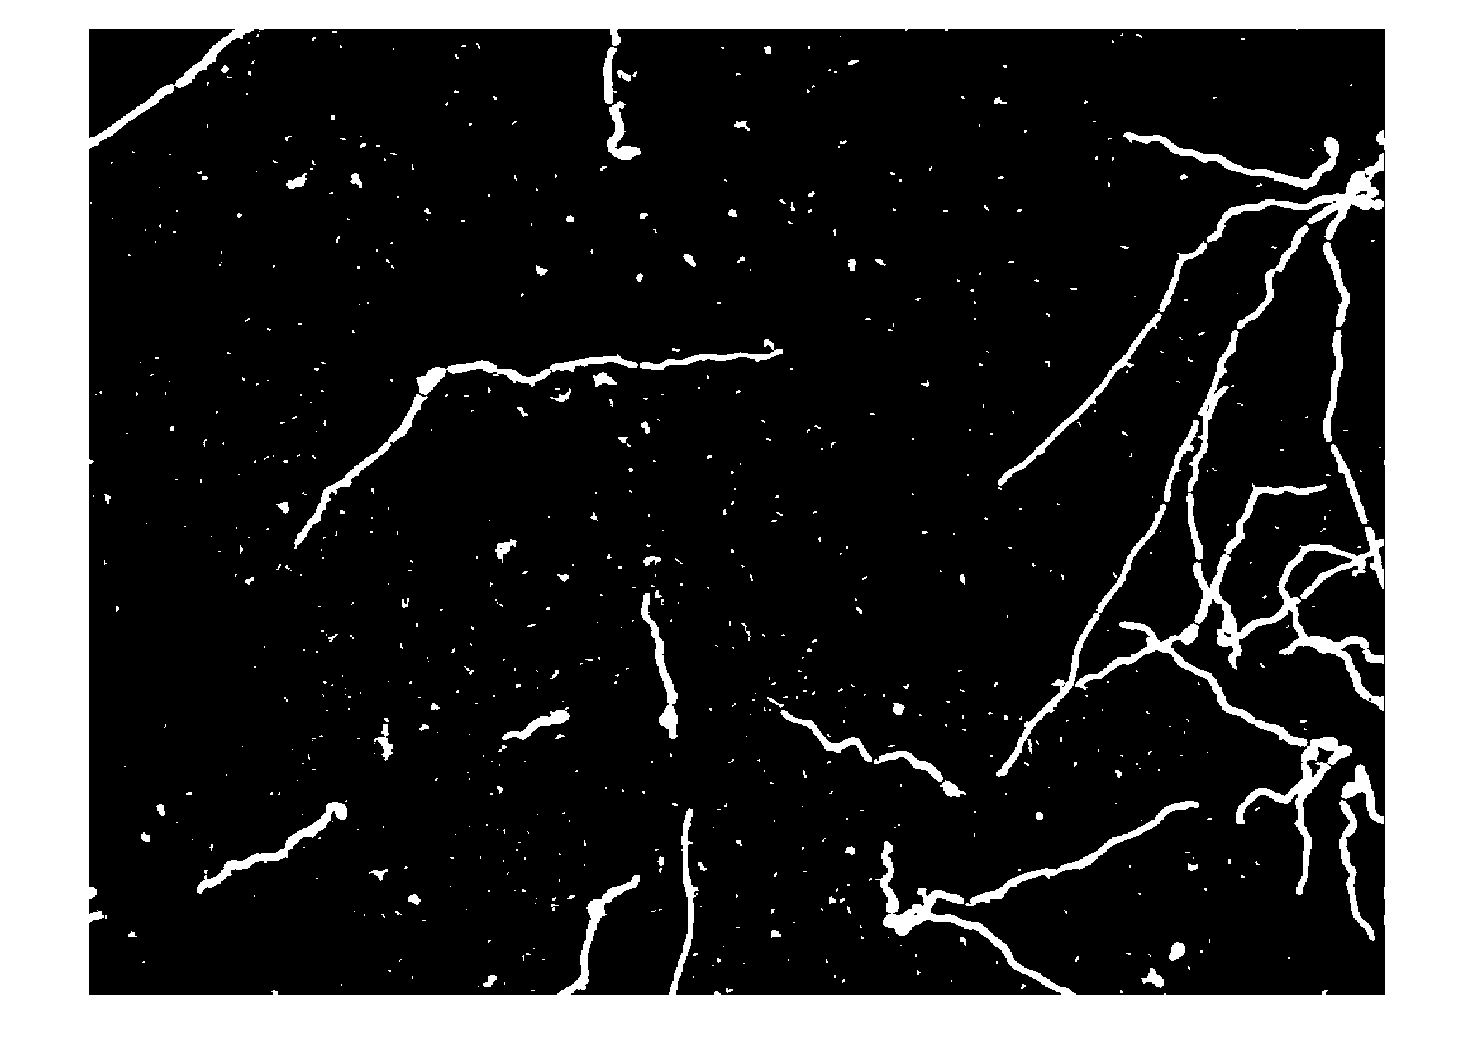

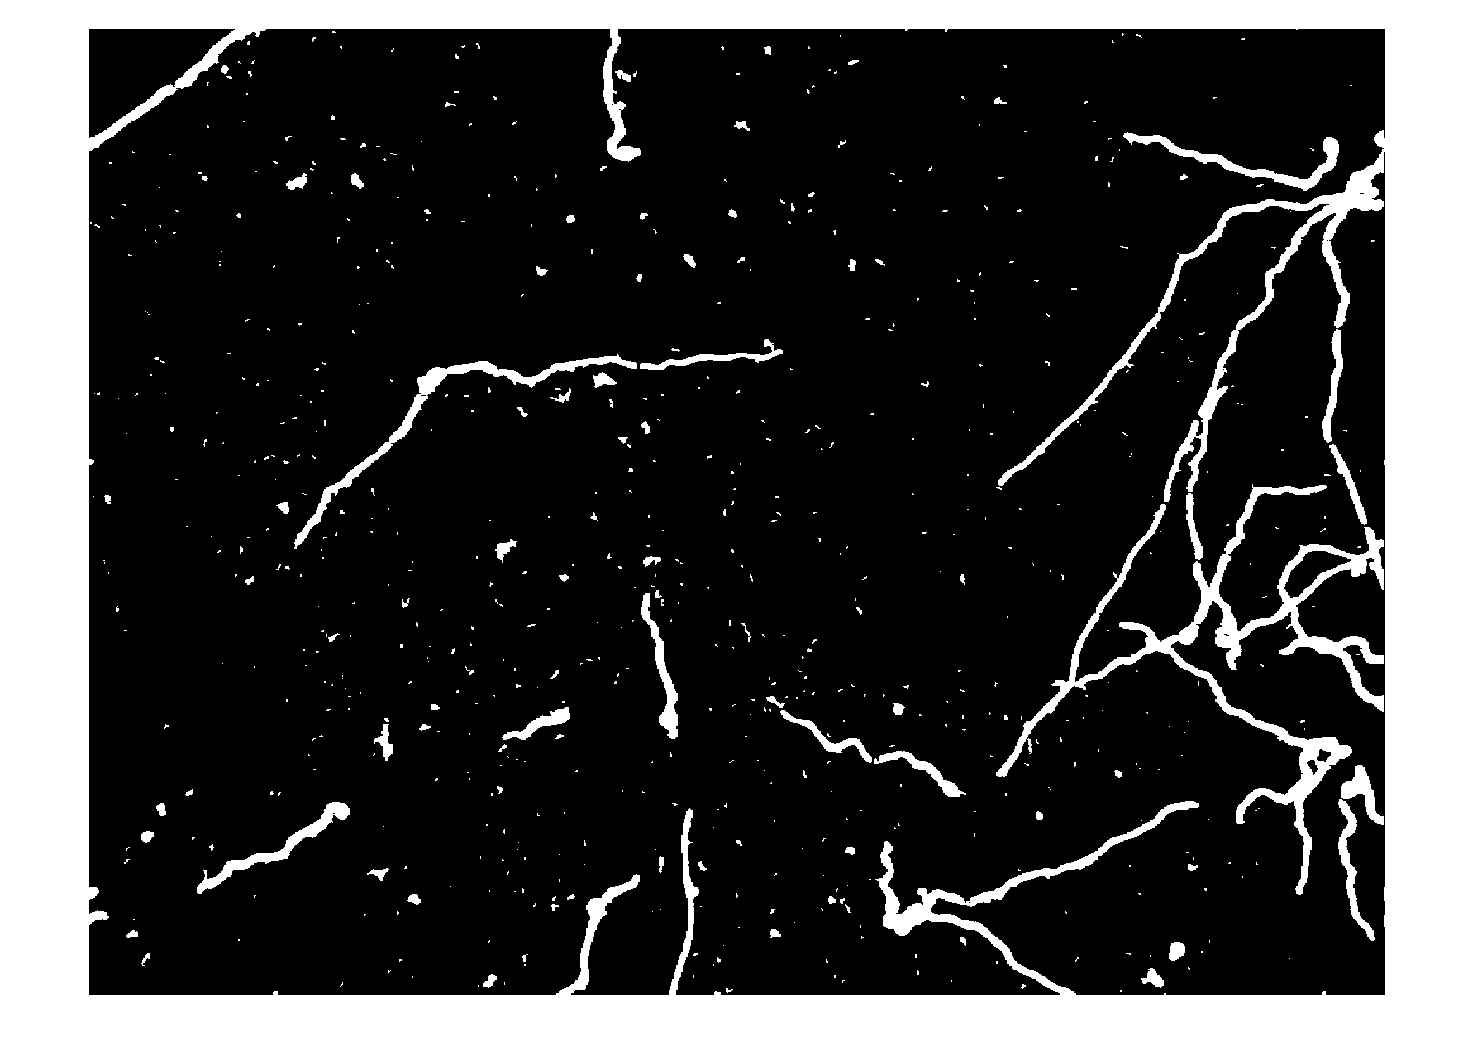

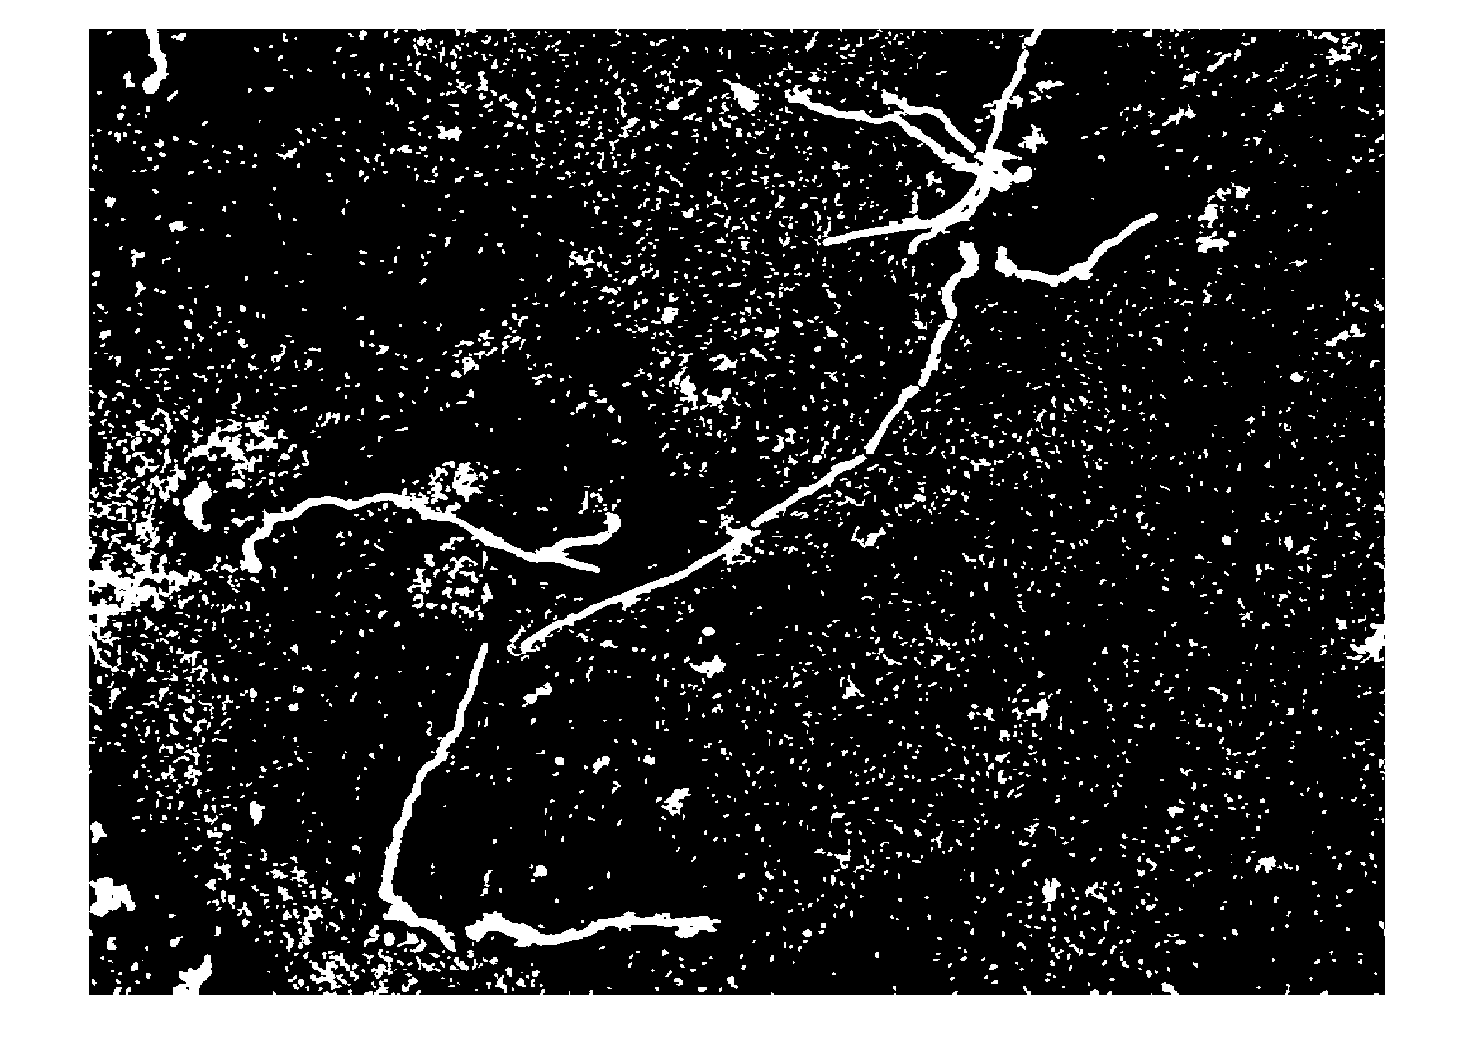

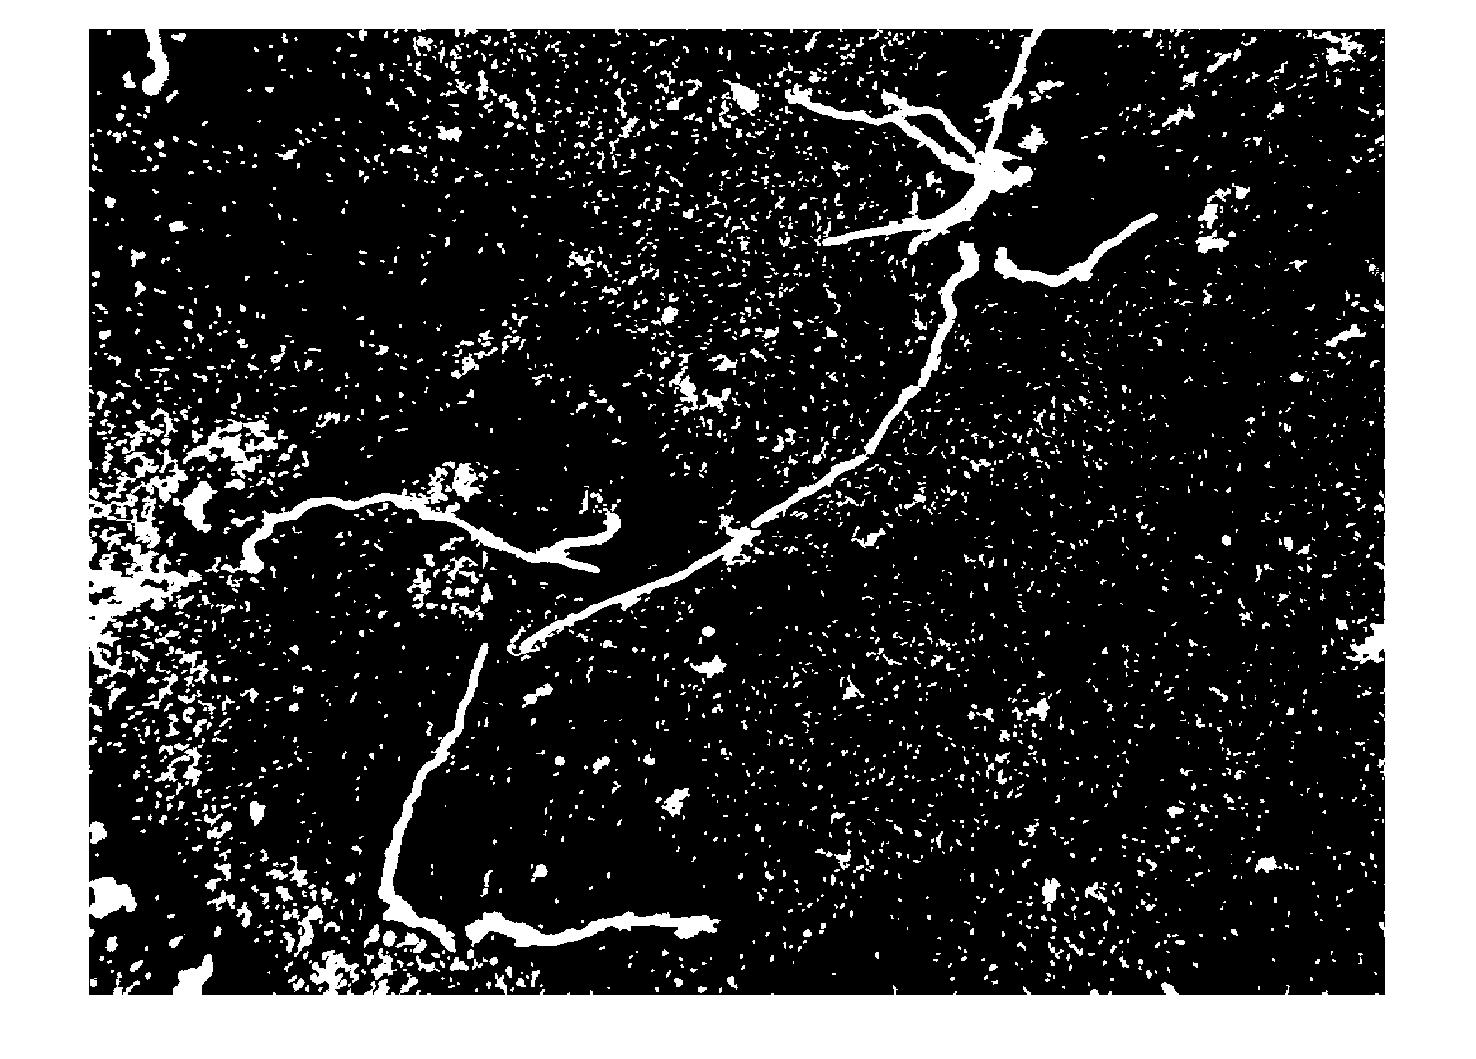

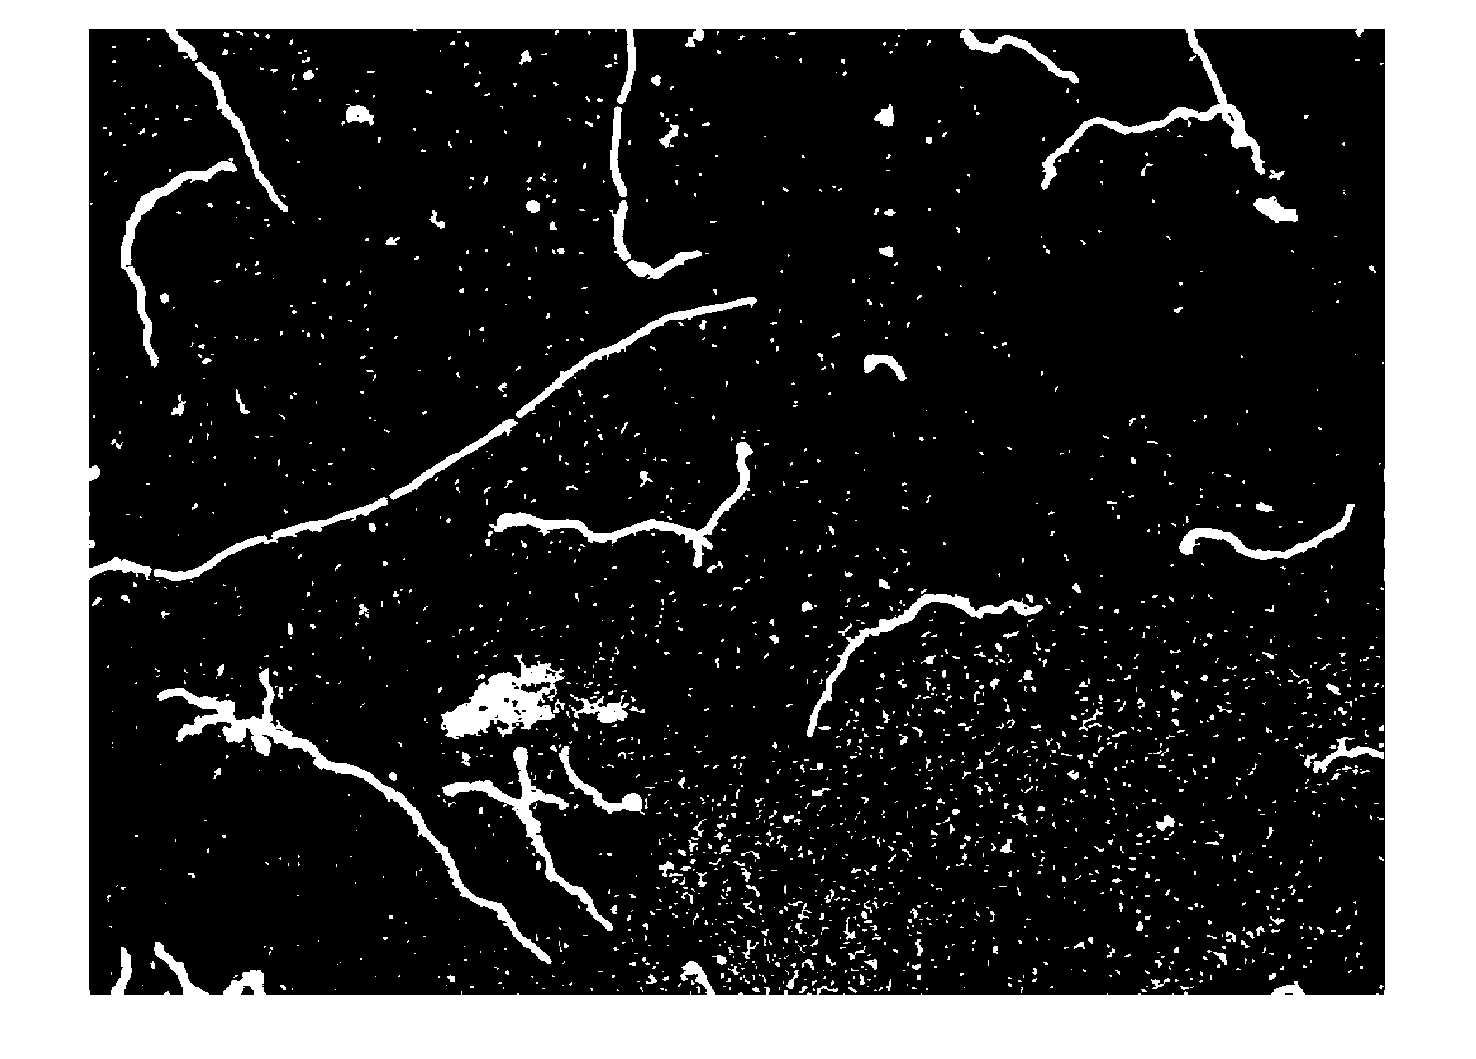

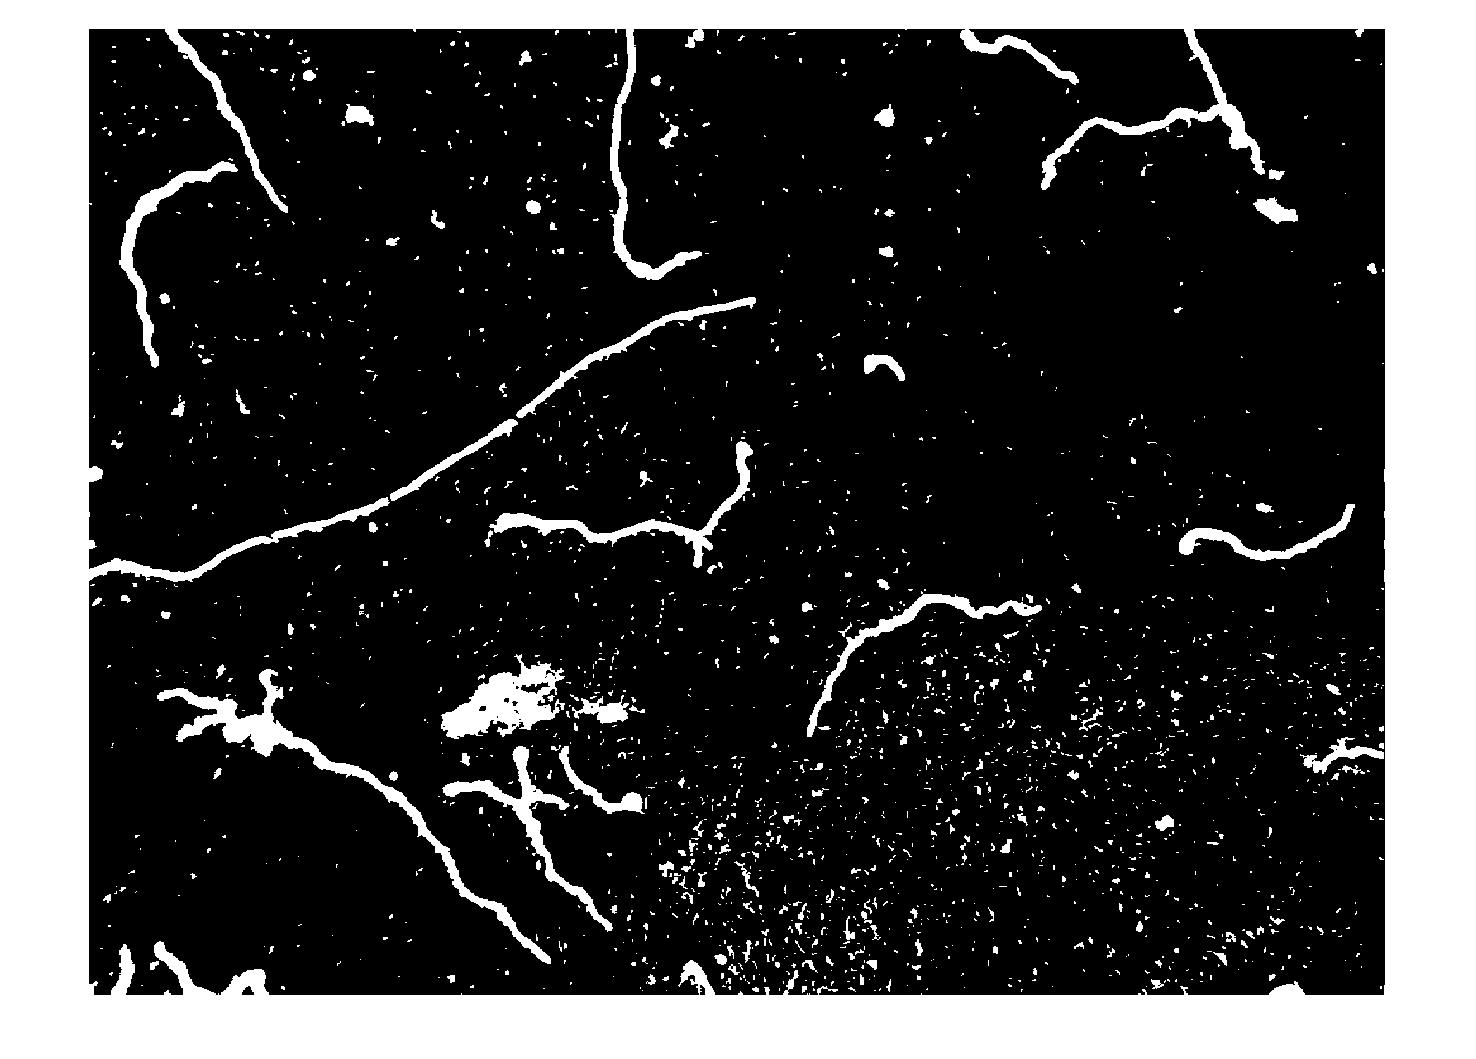

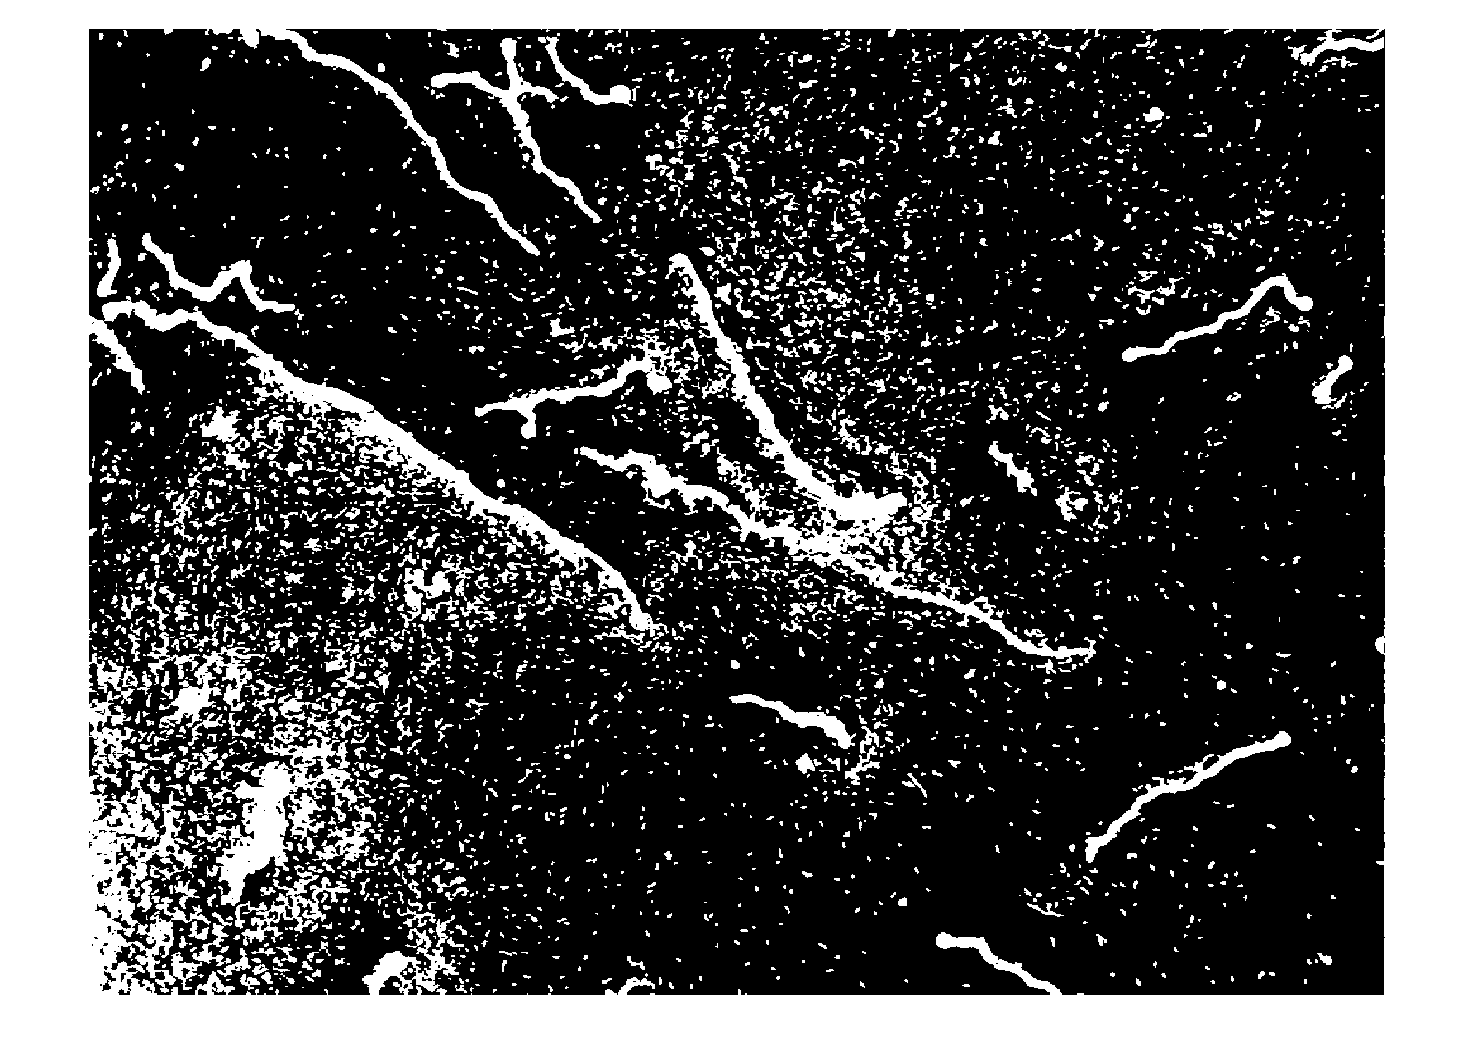

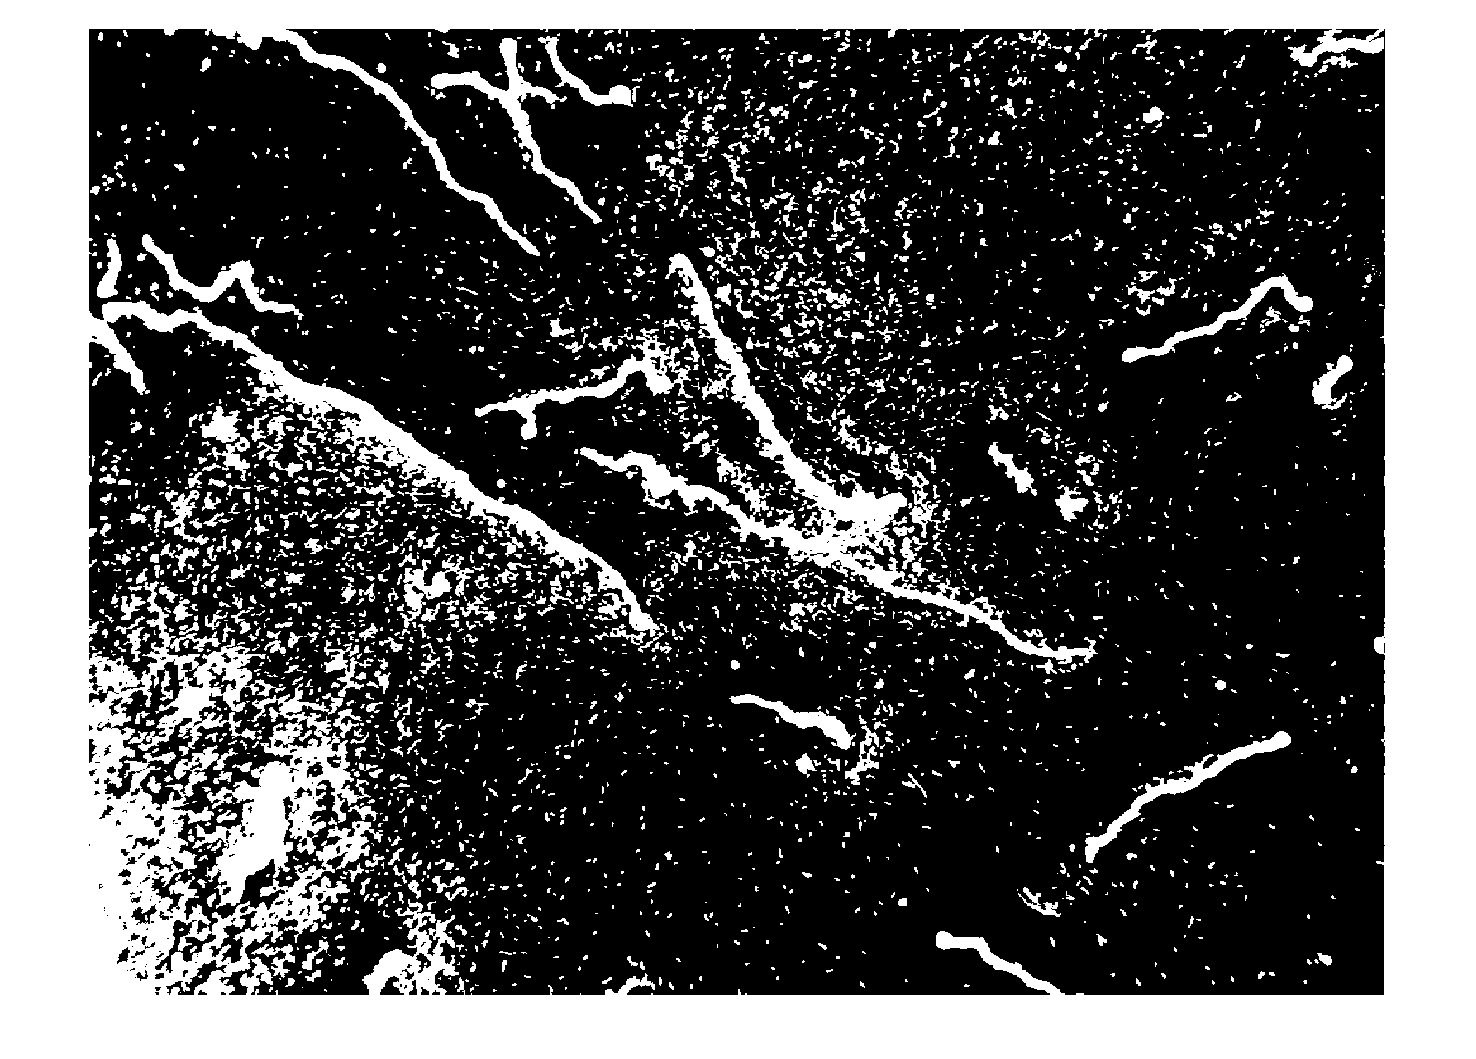

%STEP 1
%Upload images: open folder with the images of the sample.
SporesImagesPath=fullfile('D:\Spores\Images for PrecisionBio\X100\T3');
Images=imageDatastore(SporesImagesPath,'FileExtensions','.tif');

for i=1:numel(Images.Files)
    %STEP 2
    %Create BinaryImg1
    [I,info]=readimage(Images,i);
    
    labI=rgb2lab(I);
    ab=labI(:,:,1:2);
    ab=im2single(ab);
    nColors=2;
    pixel_labels=imsegkmeans(ab,nColors,'NumAttempts',3);
    BinaryImg1=imbinarize(pixel_labels);
    figure;
    imshow(BinaryImg1);
    
    gray=rgb2gray(I);
    figure;
    imshow(imcomplement(imbinarize(gray)));
%     Bin1=imbinarize(pixel_labels); %copy of BinaryImg1
%     
%     %Preliminary computations for Step 3
%     [count,pixels]=imhist(BinaryImg1);
%     black=count(1);
%     white=count(2);
%     ratio=white/black;
%     
%     SporesCenters=[];               
%     SporesRadii=[];  
%     SporesCenters2=[];               
%     SporesRadii2=[];  
%     
%     if ratio>10
%         BinaryImg1=imcomplement(BinaryImg1);
%         Bin1=BinaryImg1;
%         [count,pixels]=imhist(BinaryImg1);
%         black=count(1);
%         white=count(2);
%         ratio=white/black;
%     end
%     
%     if ratio<0.1 %Test used for STEP 3
%         %Create BinaryImg2
%         Im=rgb2gray(I);
%         Im=mat2gray(Im);
%         Im=imadjust(Im);
%         filtImage = stdfilt(Im, ones(25));
%         filtImage=imcomplement(filtImage);
%         filteredImage=imbinarize(filtImage,'adaptive','Sensitivity',0.7);
%         BinaryImg2=imcomplement(filteredImage); 
%         
%         %STEP 4
%         ConnComp_1=bwconncomp(BinaryImg2,4);
%         N_1=ConnComp_1.NumObjects;
%         stat_1=regionprops(ConnComp_1,'all');        
%         for j=1:N_1            
%             x=stat_1(j).PixelList(:,1);
%             y=stat_1(j).PixelList(:,2);
%             if stat_1(j).Area<=2000   %find not germinated spores & leftovers
%                 BinaryImg1(y,x)=0;    %delete them from binary image
%                 Bin1(y,x)=0;
%             end 
%             if  stat_1(j).Extent>=0.7 %find not germinated spores & leftovers     
%                 BinaryImg1(y,x)=0;    %delete them from binary image
%                 Bin1(y,x)=0;
%             end
%         end           
%         
%         ConnComp=bwconncomp(BinaryImg1,4);
%         N=ConnComp.NumObjects;        
%         stat=regionprops(ConnComp,'all');        
%         for j=1:N                            
%             if  stat(j).Area<=300     %find not germinated spores & leftovers       
%                 x=stat(j).PixelList(:,1);    
%                 y=stat(j).PixelList(:,2);
%                 BinaryImg1(y,x)=0;    %delete them from binary image
%                 Bin1(y,x)=0;
%             end
%         end  
%         %find spores
%         [Centers,Radii]=imfindcircles(Bin1,[11 20],'Sensitivity',0.9);     
%         [columns rows]=meshgrid(1:size(BinaryImg1,2),1:size(BinaryImg1,1));        
%         for k=1:numel(Radii)
%             x=floor(Centers(k,1));          
%             y=floor(Centers(k,2));
%             array2D = (rows- y).^2+ (columns - x).^2<(Radii(k)-6)^2;
%             
%             %test
%             if Bin1(array2D)==1 %if the circle contains only white pixels then it is a spore
%                 %viscircles([x y],Radii(k));
%                 SporesCenters=[SporesCenters;[x y]]; 
%                 SporesRadii(end+1)=Radii(k); 
%                 array2D = (rows- y).^2+ (columns - x).^2<(Radii(k))^2;
%                 Bin1(array2D)=0;   %mask pixels corresponding to spores 
%             end
%             
%         end 
%         %Repeat circles detection with different radius range: 
%         %find more circles & better correspondence with actual spores.  
%         [Centers1,Radii1]=imfindcircles(Bin1,[14 25],'Sensitivity',0.9);
%         for k=1:numel(Radii1)
%             xx=floor(Centers1(k,1));
%             yy=floor(Centers1(k,2)); 
%             array2D = (rows- yy).^2+ (columns - xx).^2<(Radii1(k)-5)^2;
%             
%             %test & keep only one copy of any double circle
%             if  isempty(SporesCenters)==0 ...
%                     & numel(find(SporesCenters==[xx yy]))==0 & Bin1(array2D)==1
%                 %viscircles([xx yy],Radii1(k));
%                 SporesCenters=[SporesCenters;[xx yy]];
%                 SporesRadii(end+1)=Radii1(k);               
%                 array2D = (rows- yy).^2+ (columns - xx).^2<(Radii1(k))^2;
%                 Bin1(array2D)=0;
%             end
%             
%         end
%         TotNumGerminatedSpores=numel(SporesRadii);
%         
%         %STEP 5
%         %remove edge touching elements
%         Threshold=(30*white)/100;                
%         Cleaned=imclearborder(BinaryImg2,8);
%         Edges=BinaryImg2-Cleaned;  
%         Edges=imfill(Edges,'holes');
%         Mask=logical(Edges);
%         BinaryImg1(Mask)=0;
%         BinaryImg1=imclearborder(BinaryImg1,8);
%         [CountP1,Pixel1]=imhist(BinaryImg1);
%         White1=CountP1(2);
%         if White1<Threshold                   
%             BinaryImg1=Bin1; %if removed too much than keep everything
%         end 
% %         figure;
% %         imshow(BinaryImg1);
%         %find remaining spores
%         [Centers,Radii]=imfindcircles(BinaryImg1,[11 20],'Sensitivity',0.9);     
%         [columns rows]=meshgrid(1:size(BinaryImg1,2),1:size(BinaryImg1,1));        
%         for k=1:numel(Radii)
%             x=floor(Centers(k,1));          
%             y=floor(Centers(k,2));
%             array2D = (rows- y).^2+ (columns - x).^2<(Radii(k)-6)^2;
%             
%             %test
%             if BinaryImg1(array2D)==1 %if the circle contains only white pixels then it is a spore
%                 SporesCenters2=[SporesCenters2;[x y]]; 
%                 SporesRadii2(end+1)=Radii(k); 
%                 array2D = (rows- y).^2+ (columns - x).^2<(Radii(k))^2;
%                 BinaryImg1(array2D)=0;   %mask pixels corresponding to spores
%                 I(array2D)=256; 
%             end
%             
%         end 
%         %Repeat circles detection with different radius range: 
%         %find more circles & better correspondence with actual spores.         
%         [Centers1,Radii1]=imfindcircles(BinaryImg1,[14 25],'Sensitivity',0.9);
%         for k=1:numel(Radii1)
%             xx=floor(Centers1(k,1));
%             yy=floor(Centers1(k,2)); 
%             array2D = (rows- yy).^2+ (columns - xx).^2<(Radii1(k)-5)^2;
%             
%             %test & keep only one copy of any double circle
%             if  isempty(SporesCenters2)==0 ...
%                     & numel(find(SporesCenters2==[xx yy]))==0 & BinaryImg1(array2D)==1
%                 SporesCenters2=[SporesCenters2;[xx yy]];
%                 SporesRadii2(end+1)=Radii1(k);               
%                 array2D = (rows- yy).^2+ (columns - xx).^2<(Radii1(k))^2;
%                 BinaryImg1(array2D)=0;
%                 I(array2D)=256;
%             end
%             
%         end
%        
%         %STEP 6
%         I(BinaryImg1)=256;
%         NumGerminatedSpores=numel(SporesRadii2)  %number of detected germinated spores
%         [CountPixels,PixelValue]=imhist(BinaryImg1);
%         
%         AreaGerminativeTubes=CountPixels(2);    %total number of white pixels           
%         AverageTubeWidth=15;
%         TotalLength=AreaGerminativeTubes/AverageTubeWidth;
%         %STEP 7
%         AverageLength=TotalLength/NumGerminatedSpores;        
%     else
%         %STEP 3
%         Im=rgb2gray(I);
%         Im=mat2gray(Im);
%         Im=imadjust(Im);
%         [Centers,Radii]=imfindcircles(Im,[6 16],'Sensitivity',0.8,'EdgeThreshold',0.1,...
%             'ObjectPolarity','dark');
%        NumNotGerminatedSpores=numel(Radii);
%     end
end